## **H1: Suoran viiva esitys**

Tehdään suoran viivan parametrinen esitys Matlabissa. Suora viiva piirretään pisteiden P0 ja P1 välille.

P0=[5,2];
P1=[10,4];

Määritellään suoran viivan yhtälöt

Px=@(u) (1-u)*P0(1)+u*P1(1);
Py=@(u) (1-u)*P0(2)+u*P1(2);

Tulostetaan funktio fplot komennolla

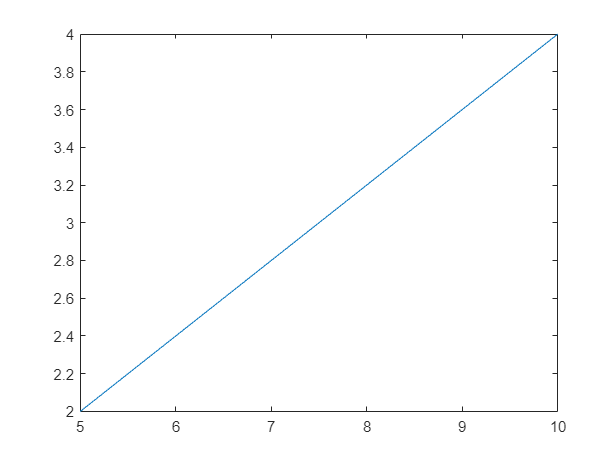

fplot(Px,Py,[0,1]);

## H1.1: Toisen asteen Spline

Ps0=[5,2];
Ps1=[10,4];
Ps2=[15,0];
Ps = [Ps0;Ps1;Ps2];

Lisätään P1 pisteen paikalle vaihteluväli

P1u=0.65

P1u = 0.6500

Z = -4

Z = -4

Matriisi A

A=[0,0,1;P1u^2,P1u,1;1,1,1]^-1*Ps;

Funktiot Px ja Py

Pxs=@(u) [u^2,u,1]*A(:,1);
Pys=@(u) [u^2,u,1]*A(:,2);

Lopuksi tulostamme splinen

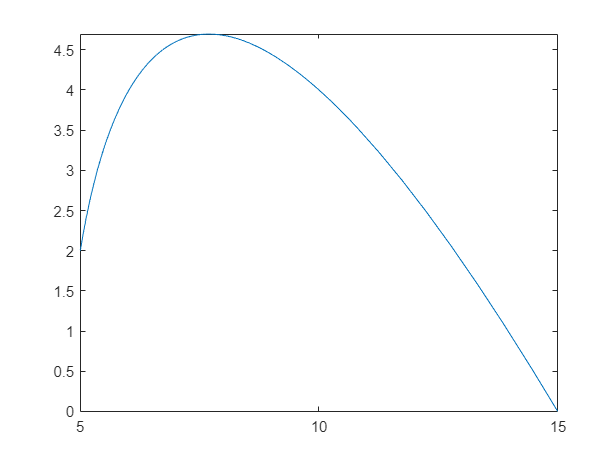

fplot(Pxs,Pys,[0,1]);